# Teorema de Green

Escrito por: Daniel Alfredo Barreras Meraz     A01254805

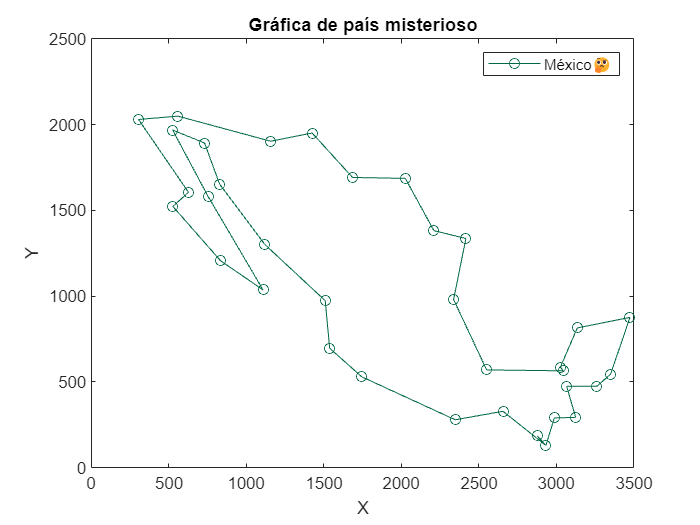

vertices = [2416.97, 1335.32; 2337.70, 979.47; 2550.86, 569.01;
            3045.88, 563.73; 3026.50, 584.87; 3135.72, 813.88;
            3475.72, 875.54; 3350.64, 544.35; 3262.56, 473.88;
            3067.02, 473.88; 3125.15, 292.43; 2987.75, 288.91;
            2933.13, 128.60; 2876.76, 184.97; 2933.13, 128.60;
            2656.56, 327.67; 2348.27, 278.34; 1745.79, 528.49;
            1537.91, 695.85; 1509.73, 972.43; 1120.40, 1300.09;
            827.97, 1652.42; 731.08, 1892.00; 524.97, 1967.75;
            753.98, 1580.19; 1108.07, 1035.85;835.02, 1204.96;
            526.73, 1522.06; 627.14, 1604.86; 304.76, 2029.41;
            558.44, 2048.79; 1157.40, 1902.57; 1425.17, 1950.14;
            1685.89, 1691.18;2025.89, 1685.89; 2210.86, 1381.13;
            2416.97, 1335.32];


x = vertices(:, 1);
y = vertices(:, 2);
plot(x, y, 'ro-', "Color", "#006847");
xlabel('X');
ylabel('Y');
title('Gráfica de país misterioso')




area = calcularArea(vertices);

fprintf("El area del terreno es de: %0.3f km^2", area);

El area del terreno es de: 2000003.155 km^2

### Función que cálcula áreas mediante el teorema de Green

%Esta función recibe un a matriz que contiene todos los vertices de un cuerpo

function area = calcularArea(vertices)
    
    n = size(vertices, 1);
    sum = 0;
    for i = 1:n
        x1 = vertices(i, 1);
        y1 = vertices(i, 2);
        if i == n
            x2 = vertices(1, 1);
            y2 = vertices(1, 2);
        else
            x2 = vertices(i+1, 1);
            y2 = vertices(i+1, 2);
        end
        sum = sum + (x2*y1 - x1*y2);
    end
    area = abs(sum) / 2;
end